Math 155 Final Project Test

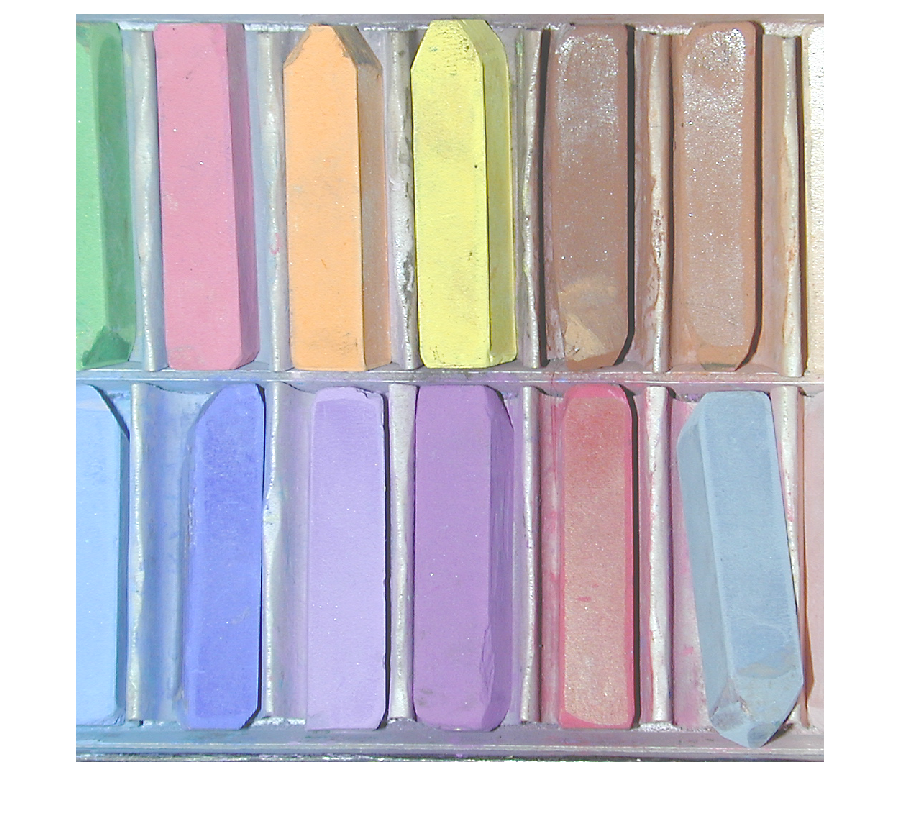

% TODO: account for color images
% TODO: use subset of images (not initial image) to construct mosaic
% TODO: account for having to resize subset images to fit in original image

clear;clc;close all;
rgb_img = imread("rgb_img.tif");
imshow(rgb_img)

% set mosaic size as scaled down from original image
scaling_factor = 10; % can change
[img_rows, img_cols, rgb_index] = size(rgb_img);
mosaic_rows = floor(img_rows/scaling_factor); % number of tiles across in mosaic
mosaic_cols = floor(img_cols/scaling_factor); % number of tiles down in mosaic

% split image into tiles that will be replaced with images later
cell_img = cell(mosaic_rows, mosaic_cols); % cell array whose entries are the tiles of the image
for i=0:mosaic_rows-1
    for j=0:mosaic_cols-1
        cell_img{i+1,j+1} = rgb_img((i*scaling_factor+1):(i+1)*scaling_factor,(j*scaling_factor+1):(j+1)*scaling_factor,:);
    end
end

% get average rgb intensity values for each orignal image tile
avg_rgb = zeros(mosaic_rows, mosaic_cols, 3);
for rgb_index=1:3
    for i=1:mosaic_rows
        for j=1:mosaic_cols
            avg_rgb(i,j,rgb_index) = mean(mean(rgb_img(i:(i+1),j:(j+1),rgb_index)));      
        end
    end
end

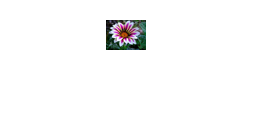

% import mosaic images - we can use other images if we want
% I just used the ones from the example to make things easier at first
listing = dir(['flowerTiles' '/*.' 'png']);
for i = 1:500
    imageName = listing(i).name;
    tiles{i} = imread(['flowerTiles' '/' imageName],'png');
end

% get average rgb values for tiles
avg_tiles = zeros(500,3);
for i=1:500
    %TODO
end

% TODO: account for resizing images to fit in grid
% or we can change how we divide up the grid

% TODO: find best fit image for each tile on grid

% TODO: construct mosaic